# `Equlibrium analysis

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

## Part 0: Initialization

Specify the dataset to analyze

% We need to specify the prefix of the project we wish to analyze
%Prefix = '2020-07-18-optoknirps_embryo1';
%Prefix = '2020-07-19-optoknirps_embryo2';
Prefix = '2020-07-19-optoknirps_embryo3';

Initialize some parameters

minAP = 0.4;
maxAP = 0.8;

analysis_start = 5;
analysis_final = 30;

test_start = 25;
test_final = 30;

maxT = 40;

eYFP_background = 1.5E5;

## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['./figure/' Prefix];

mkdir(FigPath)

% Specify the position of DynamicsResults folder
DynamicsResultsFolder = '/Users/jiaxi.zhao/Dropbox/OptoDropbox';

Now, load all the data

% Now we'll load the CompiledParticles dataset
% This generates a string that gives the path to CompiledParticles
LoadParticlePath = [DynamicsResultsFolder '/' Prefix '/CompiledParticles.mat']; 
LoadNucleiPath = [DynamicsResultsFolder '/' Prefix '/' Prefix '_lin.mat'];
LoadComNucleiPath = [DynamicsResultsFolder '/' Prefix '/CompiledNuclei.mat']; 

data.particle = load(LoadParticlePath);
data.nuclei = load(LoadComNucleiPath);
data.sch = load(LoadNucleiPath);

ElapsedTime = data.particle.ElapsedTime;
%start_frame = data.nuclei.nc14;
%final_frame = length(ElapsedTime);
start_frame = data.nuclei.nc14 + 3 * analysis_start;
final_frame = data.nuclei.nc14 + 3 * analysis_final;

test_start_frame = data.nuclei.nc14 + 3 * test_start;
test_final_frame = data.nuclei.nc14 + 3 * test_final;

ElapsedTime = data.particle.ElapsedTime-data.particle.ElapsedTime(data.nuclei.nc14);
Time = ElapsedTime(start_frame:final_frame);
APbinID = data.particle.APbinID;

## Part 2: Quality check on nuclei tracking

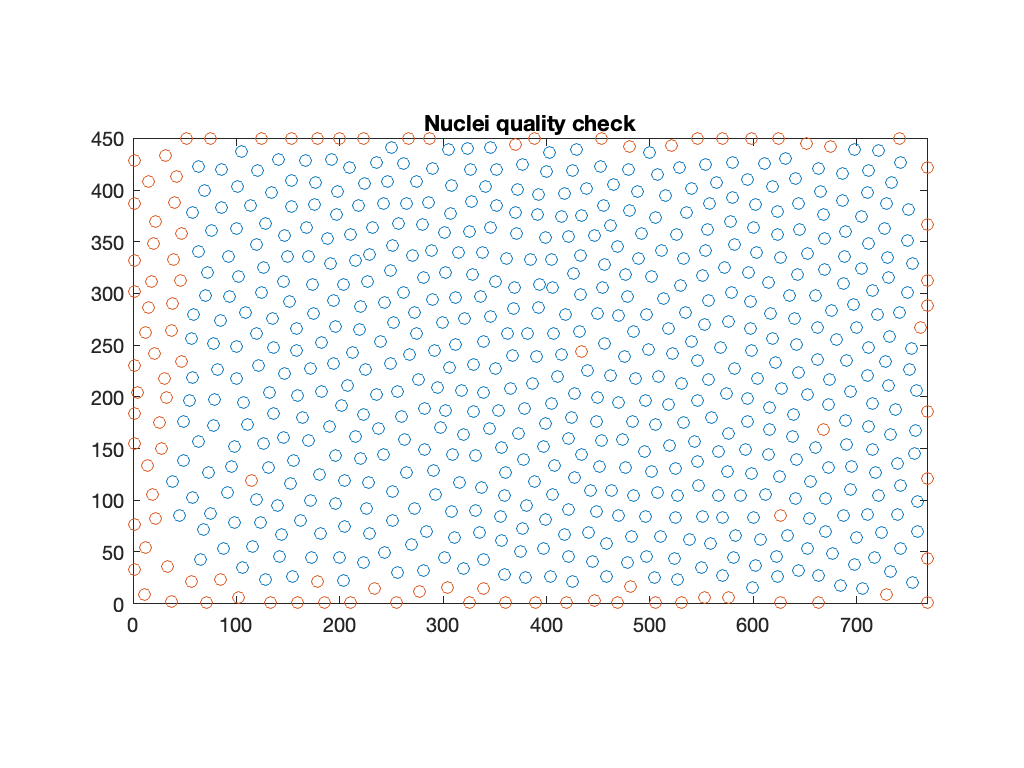

% Quality check and save the nuclei that passed the test
% Requires the nuclei to have continuous trace until lateral movement
X_pass = [];
Y_pass = [];

X_fail = [];
Y_fail = [];

sch_pass = [];

schnitzcells = data.sch.schnitzcells;

for i = 1:size(schnitzcells,2)
    index_s = find(schnitzcells(i).frames == start_frame);
    index_f = find(schnitzcells(i).frames == final_frame);
    fluo_temp = max(schnitzcells(i).Fluo(index_s:index_f,:),[],2);
    result = sum(isnan(fluo_temp));
    % quality check
    if ~isempty(index_s) && ~isempty(index_f) && (index_f-index_s == final_frame-start_frame)  ...
            && (result == 0)
        sch_pass = [sch_pass, i];
        X_pass = [X_pass, schnitzcells(i).cenx(index_s)];
        Y_pass = [Y_pass, schnitzcells(i).ceny(index_s)];
    else
        X_fail = [X_fail, schnitzcells(i).cenx(index_s)];
        Y_fail = [Y_fail, schnitzcells(i).ceny(index_s)];
    end
end

fig = figure(1);
plot(X_pass,Y_pass,'o')
hold on
plot(X_fail,Y_fail,'o')
hold off
axis equal
xlim([0 768])
ylim([0 450])
title('Nuclei quality check')

## Part 3: Compile the schnitzcells together

% Initialize storage
processed_data(1).xcoord = [];
processed_data(1).ycoord = [];

processed_data(1).schnitznum = [];
processed_data(1).NuclearFluo = [];
processed_data(1).SpotFluo = [];

% Compile all the nuclei in each frame and assign basic info
for i = 1:length(sch_pass)
    sch_now = sch_pass(i);
    index_s = find(schnitzcells(sch_now).frames == start_frame);
    index_f = find(schnitzcells(sch_now).frames == final_frame);
    
    for j = index_s:index_f
        frame_now = schnitzcells(sch_now).frames(j);
        x_coord = schnitzcells(sch_now).cenx(j);
        y_coord = schnitzcells(sch_now).ceny(j);
        fluo = max(schnitzcells(sch_now).Fluo(j,:));
        try
            processed_data(frame_now).xcoord = [processed_data(frame_now).xcoord, x_coord];
            processed_data(frame_now).ycoord = [processed_data(frame_now).ycoord, y_coord];
            processed_data(frame_now).schnitznum = [processed_data(frame_now).schnitznum, sch_now];
            processed_data(frame_now).SpotFluo = [processed_data(frame_now).SpotFluo, 0];
            processed_data(frame_now).NuclearFluo = [processed_data(frame_now).NuclearFluo fluo];  
        catch
            processed_data(frame_now).xcoord = x_coord;
            processed_data(frame_now).ycoord = y_coord;
            processed_data(frame_now).schnitznum = sch_now;
            processed_data(frame_now).SpotFluo = 0;
            processed_data(frame_now).NuclearFluo = fluo;
        end
    end
end

CompiledParticles = data.particle.CompiledParticles;

% Assign particle info to all the nuclei
for i = 1:size(CompiledParticles{1,1},2)
    schnitz_num = CompiledParticles{1,1}(i).schnitz;
    for j = 1:size(CompiledParticles{1,1}(i).Frame,2)
        frame = CompiledParticles{1,1}(i).Frame(j);
        if frame<=final_frame
            num = find(processed_data(frame).schnitznum==schnitz_num);
            processed_data(frame).SpotFluo(num) = CompiledParticles{1,1}(i).Fluo(j);
        end
    end
end

Let's try to plot the data

% {xpos = processed_data(final_frame).xcoord;
% ypos = processed_data(final_frame).ycoord;
% 
% % try to plot and test a bit...
% pts = [xpos' ypos'];
% 
% fig = figure(2);
% [v,c] = voronoin(double(pts));
% 
% for i = 1:length(c)
%     if all(c{i}~=1)
%     x = v(c{i},1);
%     y = v(c{i},2);
%     %a = processed_data(frame_plot).SpotFluo(i);
%     a = processed_data(final_frame).NuclearFluo(i);
%     patch(x,y,a);
%     colorbar
%     caxis([0 9E5])
%     end
% end
% 
% axis equal
% xlim([0 768])
% ylim([0 450])

## Part 4: Try binning by protein concentration

### Calculate Average for a moving time window

x_coord = zeros(length(sch_pass),1);
y_coord = zeros(length(sch_pass),1);
fluo = zeros(length(sch_pass),1);

% Compile all the nuclei in each frame and assign basic info
for i = 1:length(sch_pass)
    sch_num = sch_pass(i);
    index_s = find(schnitzcells(sch_num).frames == test_start_frame);
    index_f = find(schnitzcells(sch_num).frames == test_final_frame);

    x_coord(i) = mean(schnitzcells(sch_num).cenx(index_s:index_f));
    y_coord(i) = mean(schnitzcells(sch_num).ceny(index_s:index_f));
    fluo(i) = mean(max(schnitzcells(sch_num).Fluo(index_s:index_f,:)));

end


Plot the average data

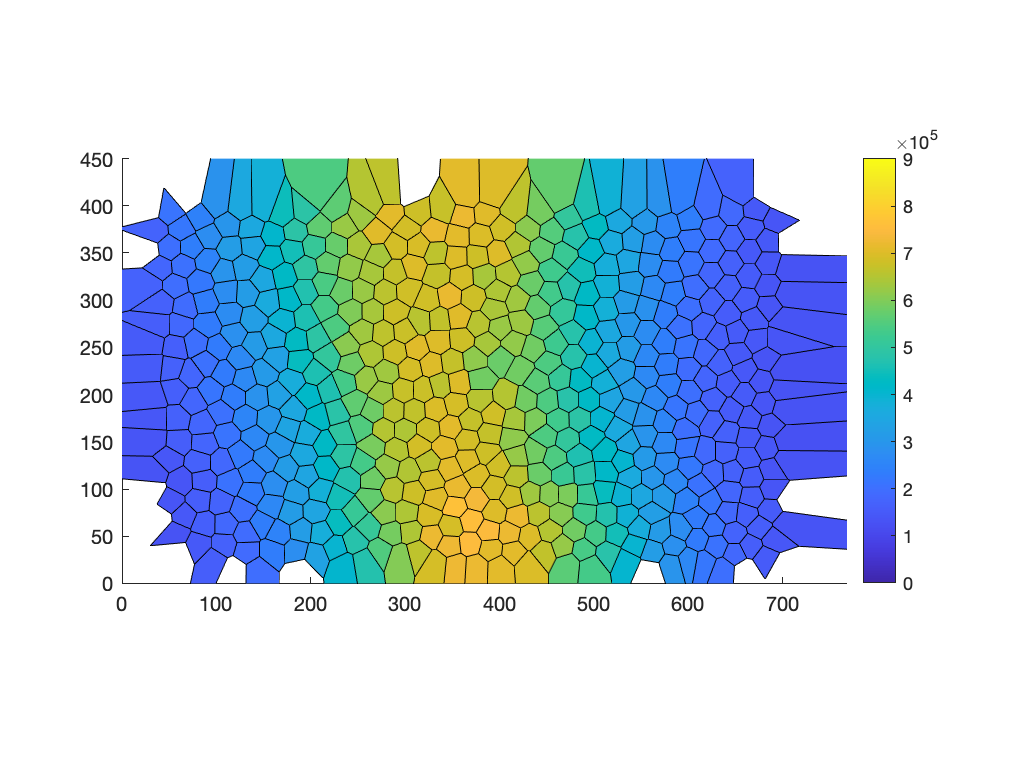

pts = [x_coord y_coord];

fig = figure(2);
[v,c] = voronoin(double(pts));

for i = 1:length(c)
    if all(c{i}~=1)
    x = v(c{i},1);
    y = v(c{i},2);
    %a = processed_data(frame_plot).SpotFluo(i);
    a = fluo(i);
    patch(x,y,a);
    colorbar
    caxis([0 9E5])
    end
end

axis equal
xlim([0 768])
ylim([0 450])

Plot the nuclear concentration

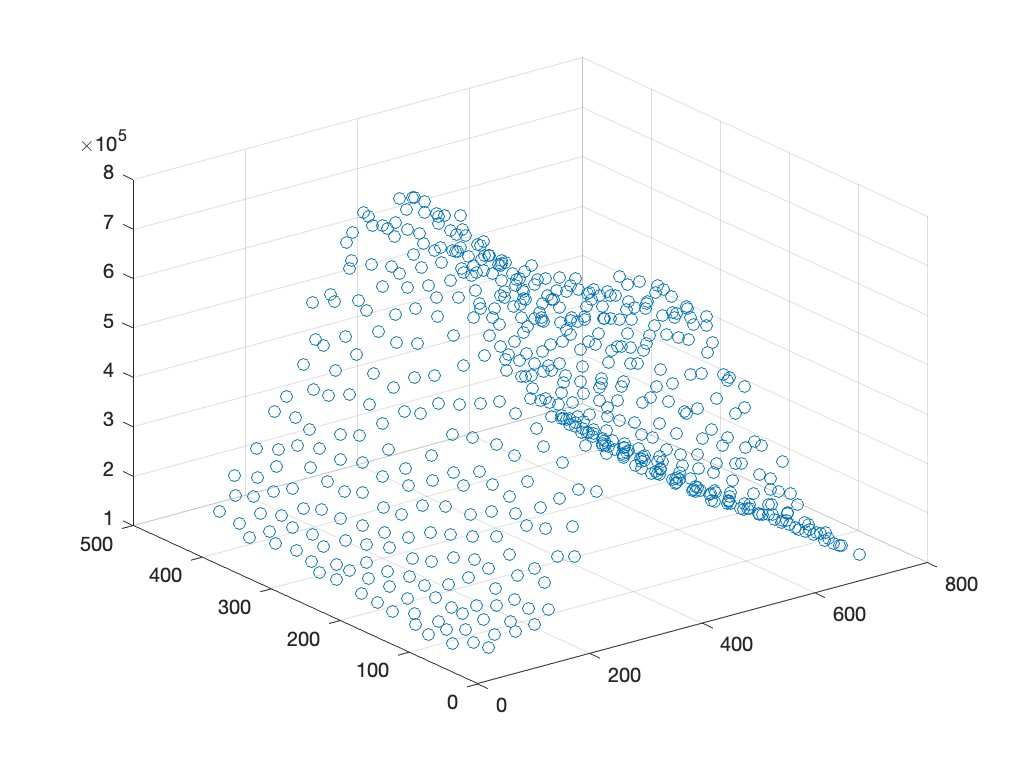

fig = figure;
scatter3(x_coord,y_coord,fluo)
savefig(fig,[FigPath,'/protein_scatter.fig'])

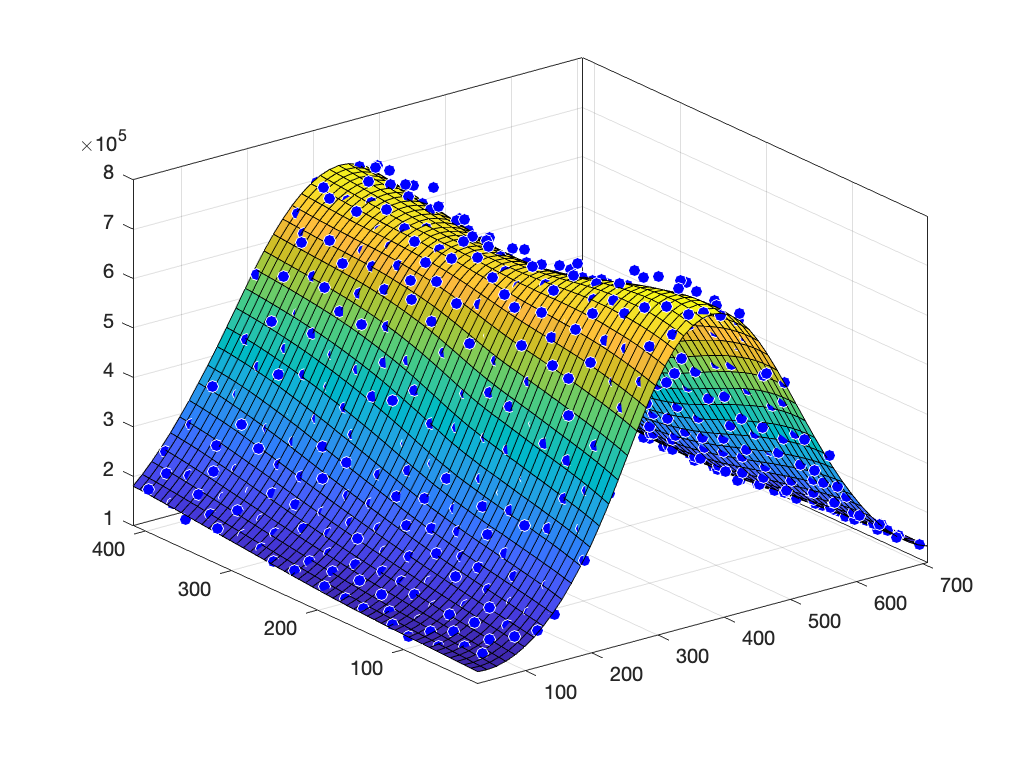


%sf1 = fit([x_coord,y_coord],fluo,'poly44');
%sf1 = fit([x_coord,y_coord],fluo,'linearinterp');
%sf1 = fit([x_coord,y_coord],fluo,'cubicinterp');
%sf1 = fit([x_coord,y_coord],fluo,'lowess');    % do not work

%sf1 = fit([x_coord,y_coord],fluo,'thinplateinterp');
%sf1 = fit([x_coord,y_coord],fluo,'biharmonicinterp');
%thinplateinterp

sf1 = fit([x_coord,y_coord],fluo,'loess'); % good, local quadratic regression

fig = figure;
plot(sf1,[x_coord,y_coord],fluo);
savefig(fig,[FigPath,'/protein_scatter_fit.fig'])

## Draw contour lines

% xlim = linspace(0,768,100);
% ylim = linspace(0,450,100);
% 
% f  = @(x,y)sf1(x,y);
% 
% 
% level = linspace(0,7E5,15);
% %fcontour(f,'LevelStepMode','manual','LevelStep',1E5)
% fcontour(f,[0 768 0 450],'LevelStep',0.25E5)
% 
% [X Y] = meshgrid(xlim,ylim);
% F = f(X,Y);
% 
% [U,V] = gradient(F);
% 
% hold on
% quiver(X,Y,U,V)
% hold off
% axis equal

## Correction for the curvature

### Try fitting the center line to quadratic function

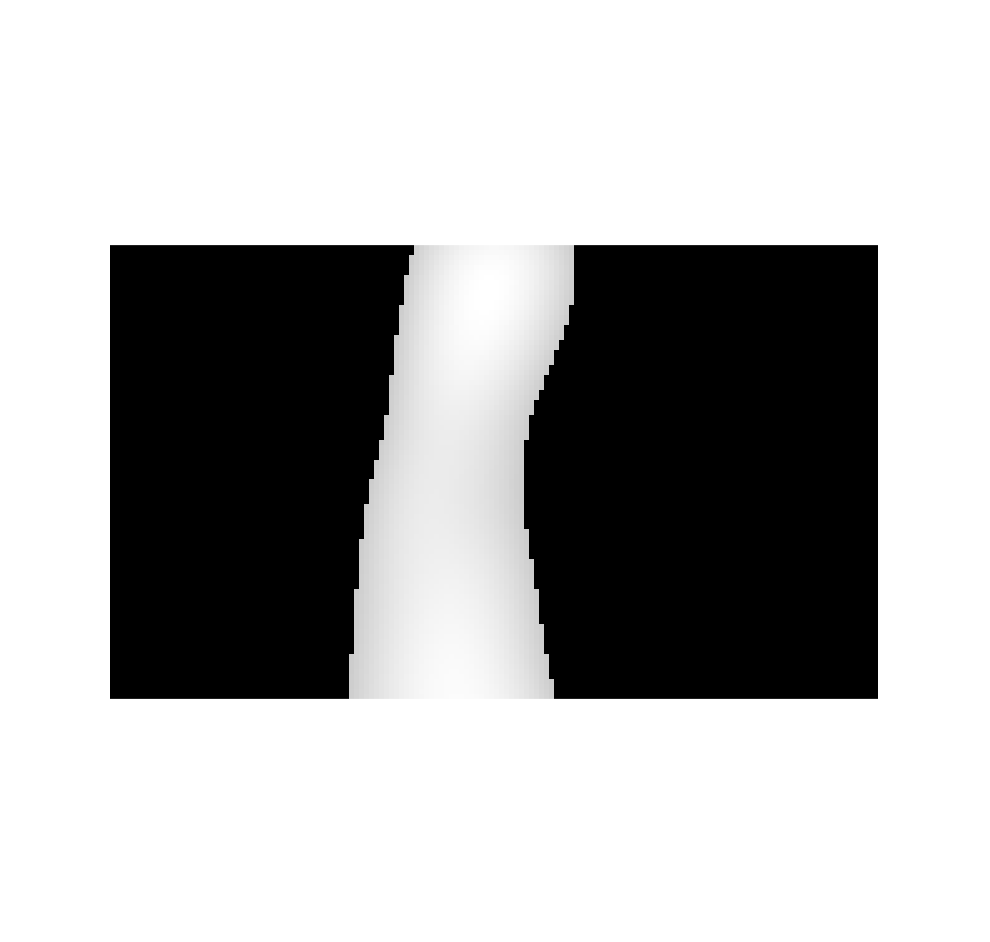

% Calculate coarse grained image
xscale = 5;
yscale = 5;

xlimit = 0:xscale:768;
ylimit = 0:yscale:450;

f  = @(x,y)sf1(x,y)-1.5E5;

[X Y] = meshgrid(xlimit,ylimit);
F = f(X,Y);

maxPeak = max(max(F));
% Extract stripe region
ImMask = F>maxPeak*0.8;
ImFluo = F.*ImMask;

fig = figure;
imshow(ImFluo,[])
truesize(fig,[512 512])

ImFluo_rot = imrotate(ImFluo,-90);
factor = length(xlimit);
k_temp = find(ImFluo_rot);
x_temp = floor(k_temp/factor)*xscale+1;
y_temp = mod(k_temp,factor)*yscale;
w = ImFluo_rot(k_temp);

%define model
%modelFun2 = @(b,x) b(1)*x.^2+b(2)*x+b(3);
modelFun3 = @(b,x) b(1)*x.^3+b(2)*x.^2+b(3)*x+b(4);

%initial condition
%start2 = [0 0 0];
start3 = [0 0 0 0];

%fit without weight
% %nlm3 = fitnlm(X(:),Y(:),modelFun2,start2);
%fit with weight
wnlm3 = fitnlm(x_temp,y_temp,modelFun3,start3,'Weight',w);

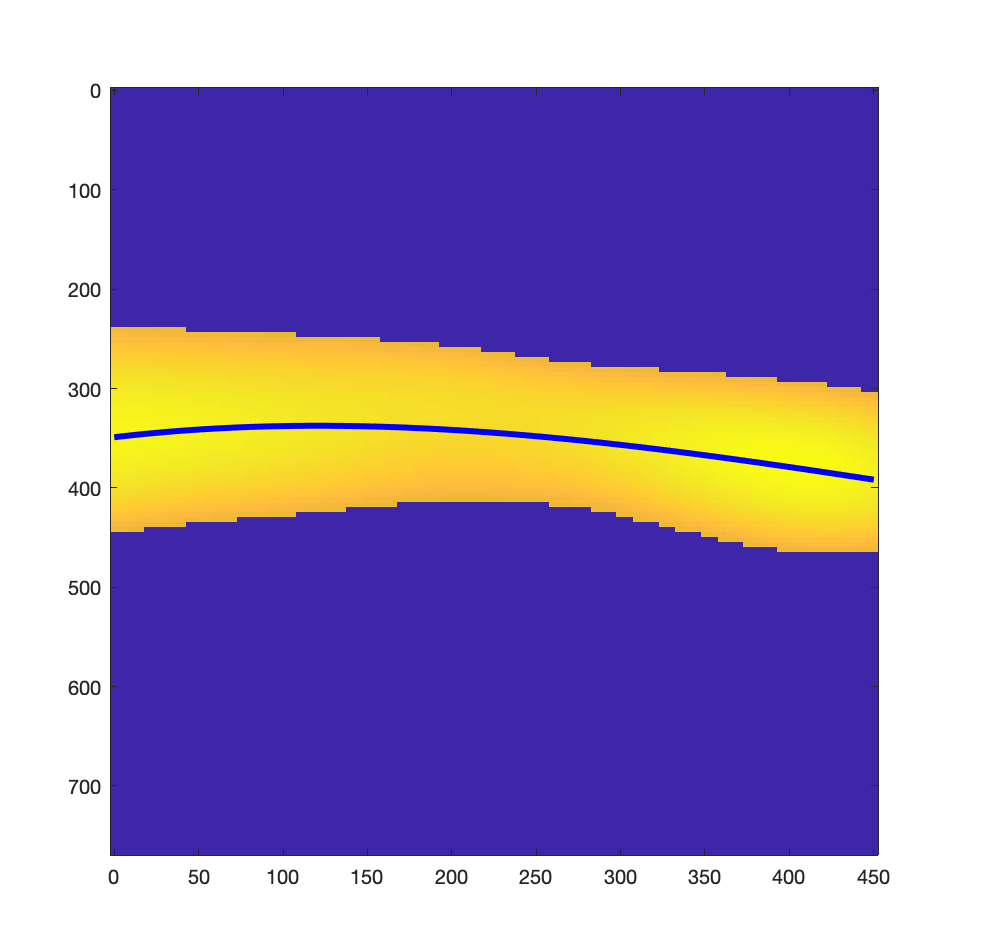

fig = figure;

x_temp = [0 450];
y_temp = [0 768];
imagesc(x_temp,y_temp,ImFluo_rot);
xx = linspace(0,450)';

dist = xlimit(2)-xlimit(1);

%plot stripe 3
%line(xx,-predict(nlm3,xx),'linestyle','--','color','k','LineWidth',1.5);
line(xx,predict(wnlm3,xx),'color','b','LineWidth',3)
truesize(fig,[512 512])

### Find four more reference lines from contour function

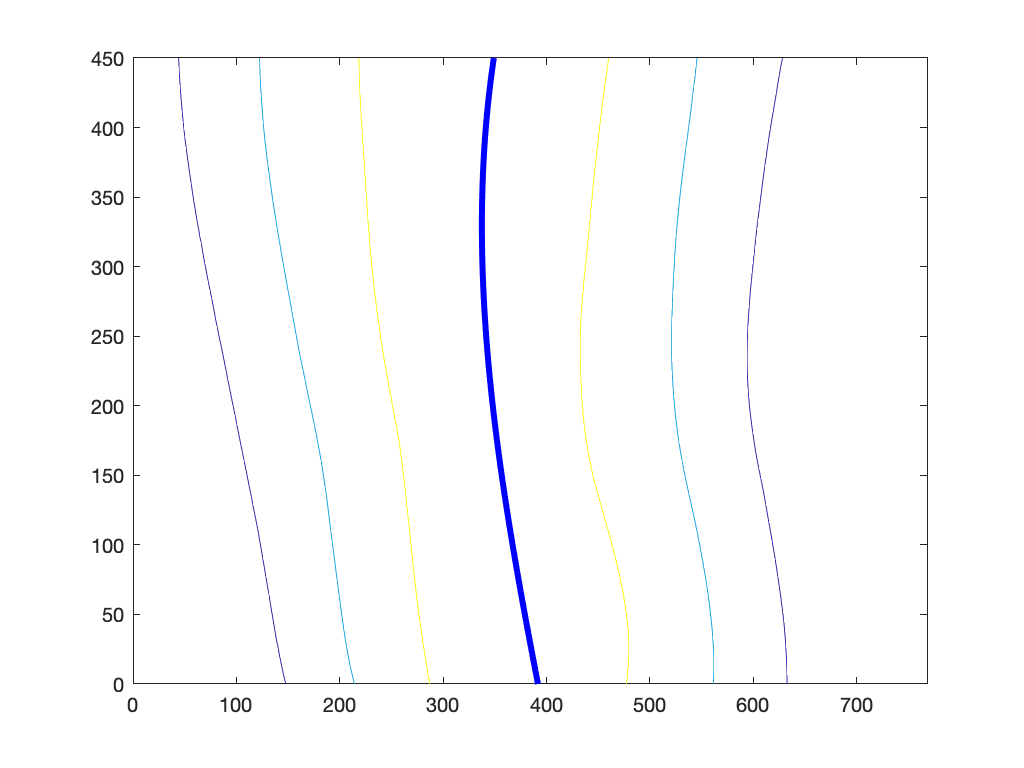

% Calculate average amplitude
avrAmp = mean(f(predict(wnlm3,xx),xx));
maxAmp = max(f(predict(wnlm3,xx),xx));
minAmp = min(f(predict(wnlm3,xx),xx));

% calculate the gaussian value based on the distance
dist = 0.5;
level1 = avrAmp * exp(-dist^2);
level2 = avrAmp * exp(-(2*dist)^2);
level3 = avrAmp * exp(-(3*dist)^2);

fig = figure;
%fcontour(f,'LevelStepMode','manual','LevelStep',1E5)
h = fcontour(f,[0 768 0 450],'LevelList',[level1,level2,level3]);
hold on
line(predict(wnlm3,xx),450-xx,'color','b','LineWidth',3)

%h = fcontour(f);
contours = h.ContourLines;

### Extract individual lines

ylimit = 0:1:450;

group1 = contours(1).VertexData(1:2,:)';
group2 = contours(2).VertexData(1:2,:)';
group3 = contours(3).VertexData(1:2,:)';

idx1 = dbscan(group1,40,3); % The default distance metric is Euclidean distance
idx2 = dbscan(group2,40,3); % The default distance metric is Euclidean distance
idx3 = dbscan(group3,40,3); % The default distance metric is Euclidean distance

% p11 = polyfit(group1(idx1==1,2),group1(idx1==1,1),3);
% p12 = polyfit(group1(idx1==2,2),group1(idx1==2,1),3);
% p21 = polyfit(group2(idx2==1,2),group2(idx2==1,1),3);
% p22 = polyfit(group2(idx2==2,2),group2(idx2==2,1),3);
% p31 = polyfit(group3(idx3==1,2),group3(idx3==1,1),3);
% p32 = polyfit(group3(idx3==2,2),group3(idx3==2,1),3);

p = zeros(7,1);
x = zeros(7,1);
k = zeros(7,1);
d = zeros(7,1);
v = zeros(7,1);

p(1) = polyfit(group1(idx1==1,2),group1(idx1==1,1),3);

Unable to perform assignment because the left and right sides have a different number of elements.

p(2) = polyfit(group1(idx1==2,2),group1(idx1==2,1),3);
p(3) = polyfit(group2(idx2==1,2),group2(idx2==1,1),3);
p(4) = polyfit(group2(idx2==2,2),group2(idx2==2,1),3);
p(5) = polyfit(group3(idx3==1,2),group3(idx3==1,1),3);
p(6) = polyfit(group3(idx3==2,2),group3(idx3==2,1),3);

for i = 1:6
    x(i) = polyval(p(i),ylimit);
    k(i) = polyder(p(i));
    d(i) = polyval(k(i),ylimit);
    v(i) = -atan(d(i))+pi/2;
end

p(7) = table2array(wnlm3.Coefficients(:,1));
x(7) = polyval(p_cen,450-ylimit);
k(7) = polyder(p_cen);
d(7) = polyval(k_cen,ylimit);
v(7) = -atan(d_cen)+pi/2;

% p_cen = table2array(wnlm3.Coefficients(:,1));
% x_cen = polyval(p_cen,450-ylimit);
% k_cen = polyder(p_cen);
% d_cen = polyval(k_cen,ylimit);
% v_cen = -atan(d_cen)+pi/2;

% x11 = polyval(p11,ylimit);
% k11 = polyder(p11);
% d11 = polyval(k11,ylimit);
% v11 = -atan(d11)+pi/2;
% 
% x12 = polyval(p12,ylimit);
% k12 = polyder(p12);
% d12 = polyval(k12,ylimit);
% v12 = -atan(d12)+pi/2;
% 
% x21 = polyval(p21,ylimit);
% k21 = polyder(p21);
% d21 = polyval(k21,ylimit);
% v21 = -atan(d21)+pi/2;
% 
% x22 = polyval(p22,ylimit);
% k22 = polyder(p22);
% d22 = polyval(k22,ylimit);
% v22 = -atan(d22)+pi/2;
% 
% x31 = polyval(p31,ylimit);
% k31 = polyder(p31);
% d31 = polyval(k31,ylimit);
% v31 = -atan(d31)+pi/2;
% 
% x32 = polyval(p32,ylimit);
% k32 = polyder(p32);
% d32 = polyval(k32,ylimit);
% v32 = -atan(d32)+pi/2;

fig = figure;
gscatter(group1(:,1),group1(:,2),idx1)
hold on
gscatter(group2(:,1),group2(:,2),idx2)
gscatter(group3(:,1),group3(:,2),idx3)

plot(x11,ylimit,'LineWidth',3)
plot(x12,ylimit,'LineWidth',3)
plot(x21,ylimit,'LineWidth',3)
plot(x22,ylimit,'LineWidth',3)
plot(x31,ylimit,'LineWidth',3)
plot(x32,ylimit,'LineWidth',3)
plot(x_cen,ylimit,'LineWidth',3)

%line(450-predict(wnlm3,xx),xx,'color','b','LineWidth',3)

xlim([0 768])
ylim([0 450])

yall = [ylimit ylimit ylimit ylimit ylimit ylimit ylimit]';
xall = [x11 x12 x21 x_cen x22 x31 x32]';
vall = [v11 v12 v21 v_cen v22 v31 v32]';

sf2 = fit([xall,yall],vall,'biharmonicinterp');
%sf2 = fit([xall,yall],vall,'thinplateinterp');
%sf2 = fit([xall,yall],vall,'poly44');
%sf2 = fit([xall,yall],vall,'loess');

fig = figure;
plot(sf2,[xall,yall],vall);

### Calculate the vector field

[xq,yq] = meshgrid(-50:20:818,-50:20:500);
vq = sf2(xq,yq);
%vq_int = interp2(xq(isnan(vq)),yq(isnan(vq)),vq(isnan(vq)),xq,yq);
e_x = sin(vq);
e_y = -cos(vq);

yrange = -50:1:500;

% plot vector field and lines
fig = figure;
hold on
plot(polyval(p11,yrange),yrange,'LineWidth',3)
plot(polyval(p12,yrange),yrange,'LineWidth',3)
plot(polyval(p21,yrange),yrange,'LineWidth',3)
plot(polyval(p22,yrange),yrange,'LineWidth',3)
plot(polyval(p31,yrange),yrange,'LineWidth',3)
plot(polyval(p32,yrange),yrange,'LineWidth',3)
plot(polyval(p_cen,yrange),450-yrange,'LineWidth',3)

quiver(xq,yq,e_x,e_y)

starty = 0:32:512;
%starty = predict(wnlm5,startx');
startx = 1*ones(1,length(starty));
hlines = streamline(xq,yq,e_x,e_y,startx,starty);
set(hlines,'LineWidth',2,'Color','r')
axis([-100 868 -100 550])
axis equal

### Given a point, calculate its coordinate

x = 300;
y = 400;

n11 = polyval(p11,y);
n12 = polyval(p12,y);
n21 = polyval(p21,y);
n22 = polyval(p22,y);
n31 = polyval(p31,y);
n31 = polyval(p31,y);
n_cen = polyval(p31,y);


### Try registration strategy

Make reference figure

xcen = 384.5;
A = 7E5;

xlimit = 1:1:768;
ylimit = 1:1:450;

[X Y] = meshgrid(xlimit,ylimit);
RefGauss = A*exp(-(X-xcen).^2/5E4);

fig = figure;
imagesc(RefGauss)
caxis([0 7E5])

Generate smoothened, actual nuclear concentration

ActNuc = f(X,Y);

fig = figure;
imagesc(ActNuc)
caxis([0 7E5])

Image registration

imshowpair(RefGauss, ActNuc,'Scaling','joint')
[optimizer, metric] = imregconfig('multimodal');
optimizer.InitialRadius = 1E-2;
optimizer.Epsilon = 1.5e-4;
optimizer.GrowthFactor = 1.01;
optimizer.MaximumIterations = 300;

tform = imregtform(RefGauss, ActNuc, 'affine', optimizer, metric);


% Plot mean vector
MeanFig = figure;
imagesc(APbinID,Time,data.particle.MeanVectorAP{1}(start_frame:final_frame,:));
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([minAP maxAP])
ylim([0 maxT])

% Plot fraction on
OnFig = figure;
imagesc(APbinID,Time,data.particle.OnRatioAP{1}(start_frame:final_frame,:));
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([minAP maxAP])
ylim([0 maxT])

% Plot mean vector (all nuclei)
data_plot = data.particle.OnRatioAP{1}.*data.particle.MeanVectorAP{1};

MeanAllFig = figure;
imagesc(APbinID,Time,data_plot(start_frame:final_frame,:));
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([minAP maxAP])
ylim([0 maxT])
title('Mean Spot Fluorescence')
colorbar
caxis([0 2E5])
saveas(MeanAllFig,[FigPath '/MeanSpot_fluo.pdf' ]);

### For nuclei

data_plot = data.nuclei.MeanVectorAP(start_frame:final_frame,:);
%data_plot = data.nuclei.MeanVectorAP(start_frame:final_frame,:)/correction_factor;
% Embryo 7/10
%data_plot(1:switch_frame-1) = data_plot(1:switch_frame-1)/correction_factor_1;
%data_plot(switch_frame:end) = data_plot(switch_frame:end)/correction_factor_2;

MeanNucleiFig = figure;
imagesc(APbinID,Time,data_plot);
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([minAP maxAP])
ylim([0 40])
colorbar
caxis([0 12E5])
title('Mean Protein Fluorescence')
saveas(MeanNucleiFig,[FigPath '/MeanProtein_fluo.pdf' ]);

## Part 3: Plot nuclei concentration